# Lab 9.1: PID Control Design for Buck Converters

## Response of the Buck Converter

Tapping back into the first few labs you did in the semester, you need to get an understanding of the system you are trying to control. To do this, you can use the following transfer function (which I recommend deriving on your own) to see the step and impulse responses of the circuit. 


$$\frac{V_o}{D} = \frac{\frac{V_{in}}{LC}}{s^2+s\left(\frac{1}{R_oC}+\frac{R_L}{L}\right)+\left(\frac{1}{LC}+\frac{R_L}{R_oLC}\right)}$$


For an example system, you can use the following values for your system.

- 
$$V_{in} = 24V$$


- 
$$V_{out} = 18V$$


- 
$$R_{load} = 100\Omega$$


- 
$$F_s = 50kHz$$


- 
$$L = 1.7mH$$


- 
$$C = 0.75\mu F$$


- ESR of Inductor $R_L = 0.08\Omega$

- ESR of Capacitor $R_C = 0.03\Omega$

*Insert whatever you need here, including code blocks, pictures, etc.*

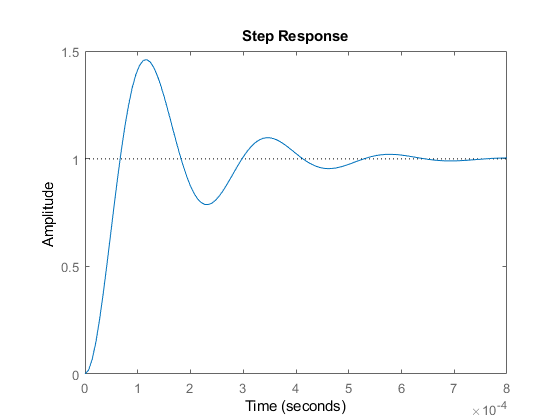

D = 1;
L = 1.7*10^-3;
C = 0.75*10^-6;
R_load = 100;
R_L = 0.08;
syms s;
G = tf([D/(L*C)], [1 (1/(R_load * C) + R_L/L) (1/(L*C) + R_L/(R_load*L*C))]);
figure(1);
step(G);

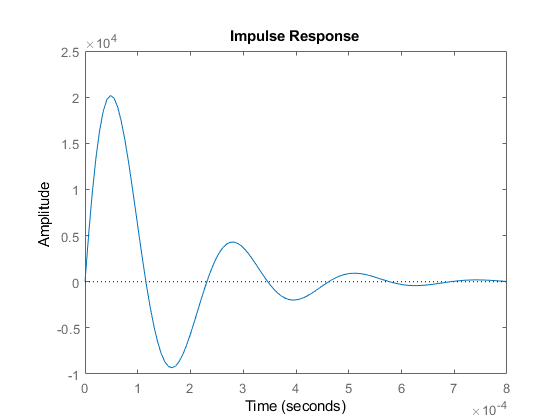


figure(2);
impulse(G);

## Controlling the transient response of the Buck Converter

Now that you hopefully have a decent idea of how this circuit is meant to operate, you can begin to tune the response of the system to fit your needs. For now, we are holding the output resistance (load current) steady, but we will eventually be changing that to really see if the control loop is working. 

There is literally an entire course we offer on how to pick these values and its impact on system performance, but for now, you should tune a PID controller to force your Buck Converter to have the following transient characteristics. These can be dependent on things like switching characteristics of the FETs, load type, input impedence, etc.

- Steady State Error = 0%

- Rise Time = 0.719ms

- Settling Time = 1.32ms

- % Ripple = 0.56%

- Peak Time = 1ms

You will need to tune the PID which is already in the Simulink file. Make sure you document how you are go about your tuning and the steps you took.

## Let's get real with this circuit

One of the biggest assumptions that has been made for you this whole time is that the input voltage is consistent and the load current is consistent as well. I hope you can imagine pretty quickly that you cannot have a system with these perfect situations. Whether it is battery powered, renewables, or other methods of powering the device the input voltage is bound to change over time, but your buck converter still needs to be consistent.

### Varriance in Input Voltage

Originally, there was going to be solar panels hooked up to the input, which can varry in voltage, current, and impendance based on the amount of light on them. In order to see the impact of some of these variances, you should probe your newly tuned Buck Converter to see if they still would work in the situation.  For all of these, you should also look at plotting the duty cycle of the system throughout the response, which is basically seeing how your system is responding.

#### DC Offset

To simulate minor change in day-to-day operations such as clouds passing overhead which are slow compared to the response time of the system.

Apply a $\pm 10\%$ offest to the input of your system and plot the response versus the original input voltage. Compare the duty cycles during the transient period and the steadystate period.

Next, apply a $\pm 20\%$ and perform the same analysis.

#### DC with Sinusoid

To account for things like noise from the power lines, environmental noise, etc., we should corrupt our input voltage with a pure sine wave focusing on a few key frequencies which we would be present. 

Apply a 60hz Sine Wave superimposed on the DC input from the original circuit with an amplitude 1/20th of the DC value. Plot the output and compare how well the buck converter rejects the noise. Do the same for 1/10th the DC voltage.

### Noise in the feedback

Since this cirucit depends heavily on the use of feedback, we need to ensure that noise introduced by the switching circuit doesnt corrupt the performance of the output. There are going to be two sources of noise you need to see if there is a resiliance to: Switching Noise, and Random Noise.

#### Switching Noise

Since the FET is swtiching at a particular frequency, this noise (and its harmonics) are going to propegate throughout the circuit, including the feedback path. Using a summing junction, add a sinusoidal source with voltage 1/20th the ideal output voltage, and a frequency of that used in the switching circuit. Plot the output as well as the duty cycle and determine if the system can reject the noise.

#### Environmental Noise

Do the same as above, but utilize a white noise source instead of a pure sine wave. 

### Variance in Output

This is truly where the most realistic impact is going to be in your system. Up to this point, the load impedance has not changed, but when you are powering something, the required current needed by the load is going to change based on what it is doing. To help simulate this, I am going to pull from an example in IoT, Low Power Sensor Nodes. These devices mostly sleep throughout the day, only waking up to take measurements and report information. We are going to speed things up a bit and make a sysem which really reports almost too much for some of these applications.

To simulate a node using something like Bluetooth or LoRa to communicate, we are only going to focus on two modes: Sleep, and Transmit. Our node is going to report measurements once every second, which is going to put a heavy draw on the buck converter. For our example sensor node, assume that every second, the system sits idle for 900ms and actively transmits for 100ms. The current draws for these modes are:

- Idle: 0.1mA

- Active: 100mA

Your tasks is to change $R_{Load}$to reflect these changes in current draws and to monitor the performance of the circuit during the periods of transition. You need to ensure that the circuit is performing as expected and is within the performance specs laid out when you designed the controller. Determine the impact of a longer active period on the circuit, and if there would be a point where the circuit would "fail" in providing the correct output voltage.